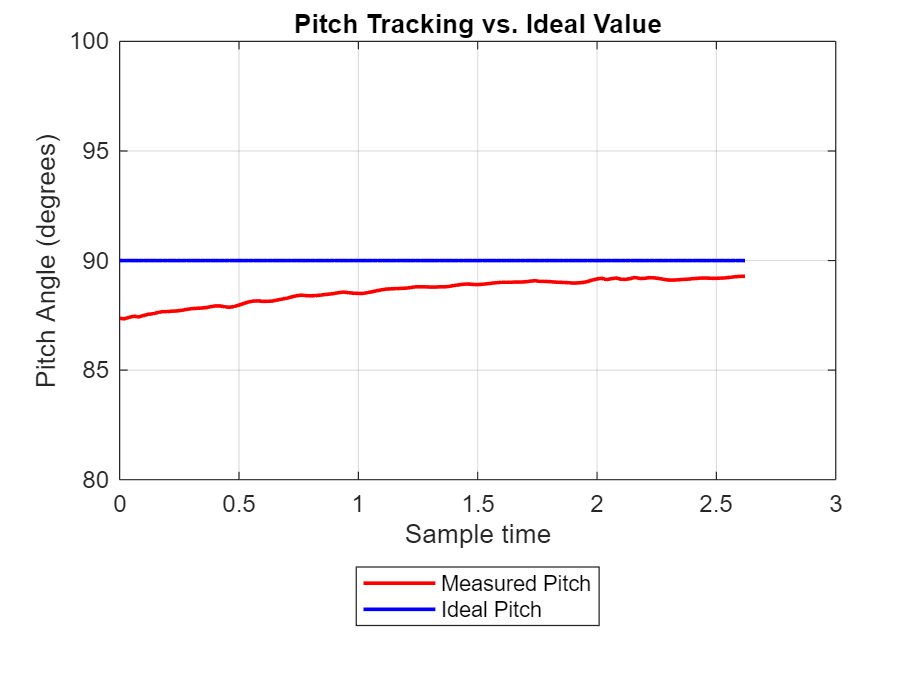

% Real (measured) and Ideal pitch angle values
real_pitch = [ ...
 87.36, 87.34, 87.41, 87.46, ...
87.43, 87.49, 87.55, 87.57, 87.63, 87.67, 87.67, 87.69, 87.70, 87.73, ...
87.77, 87.80, 87.82, 87.83, 87.85, 87.89, 87.93, 87.93, 87.89, 87.87, ...
87.90, 87.97, 88.04, 88.11, 88.15, 88.16, 88.14, 88.14, 88.15, 88.20, ...
88.24, 88.28, 88.34, 88.39, 88.42, 88.40, 88.39, 88.40, 88.42, 88.45, ...
88.47, 88.50, 88.54, 88.56, 88.53, 88.51, 88.50, 88.50, 88.54, 88.58, ...
88.63, 88.67, 88.70, 88.71, 88.72, 88.73, 88.74, 88.77, 88.80, 88.80, ...
88.80, 88.79, 88.79, 88.80, 88.80, 88.82, 88.86, 88.89, 88.92, 88.93, ...
88.91, 88.90, 88.92, 88.94, 88.97, 88.99, 89.01, 89.01, 89.01, 89.02, ...
89.02, 89.03, 89.06, 89.08, 89.05, 89.05, 89.04, 89.02, 89.01, 89.00, ...
88.99, 88.97, 88.98, 89.00, 89.04, 89.11, 89.16, 89.19, 89.13, 89.17, ...
89.20, 89.15, 89.14, 89.18, 89.23, 89.18, 89.19, 89.22, 89.21, 89.18, ...
89.14, 89.11, 89.11, 89.12, 89.14, 89.15, 89.17, 89.19, 89.20, 89.20, ...
89.19, 89.19, 89.20, 89.21, 89.24, 89.26, 89.28, 89.28 ...
];


ideal_pitch = 90 * ones(size(real_pitch)); % constant ideal value


% Generate time vector (0.02 s per sample)
sample_interval = 0.02; % seconds
num_samples = length(real_pitch);
time = (0:num_samples-1) * sample_interval;

figure;
plot(time, real_pitch, 'r', 'LineWidth', 1.5);
hold on;
plot(time, ideal_pitch, 'b-', 'LineWidth', 1.5);
legend('Measured Pitch', 'Ideal Pitch', 'Location', 'southoutside');

xlabel('Sample time');
ylabel('Pitch Angle (degrees)');
title('Pitch Tracking vs. Ideal Value');
ylim([80 100]); % Set y-axis from 0 to 100
grid on;